clear
tic

## 生成理想的Vout信号

N = 16;
Fs = 2E6;                                   % sample rate: 2MHz
M = 210000;
Fin = Fs / M;

len_seg = M;
num_seg = 10;
Vout_array = zeros([len_seg, num_seg]);
Gain = 15.2815;
Vin_amp = 1.8023;
Vin_offset = 3.1332E-4;

t = (0:len_seg-1)/Fs;
phi0 = (rand(1, num_seg)*2-1)*pi;

for i = 1:num_seg
    Vout_array(:,i) = Vin_amp *sin(2*pi*Fin*t);
end




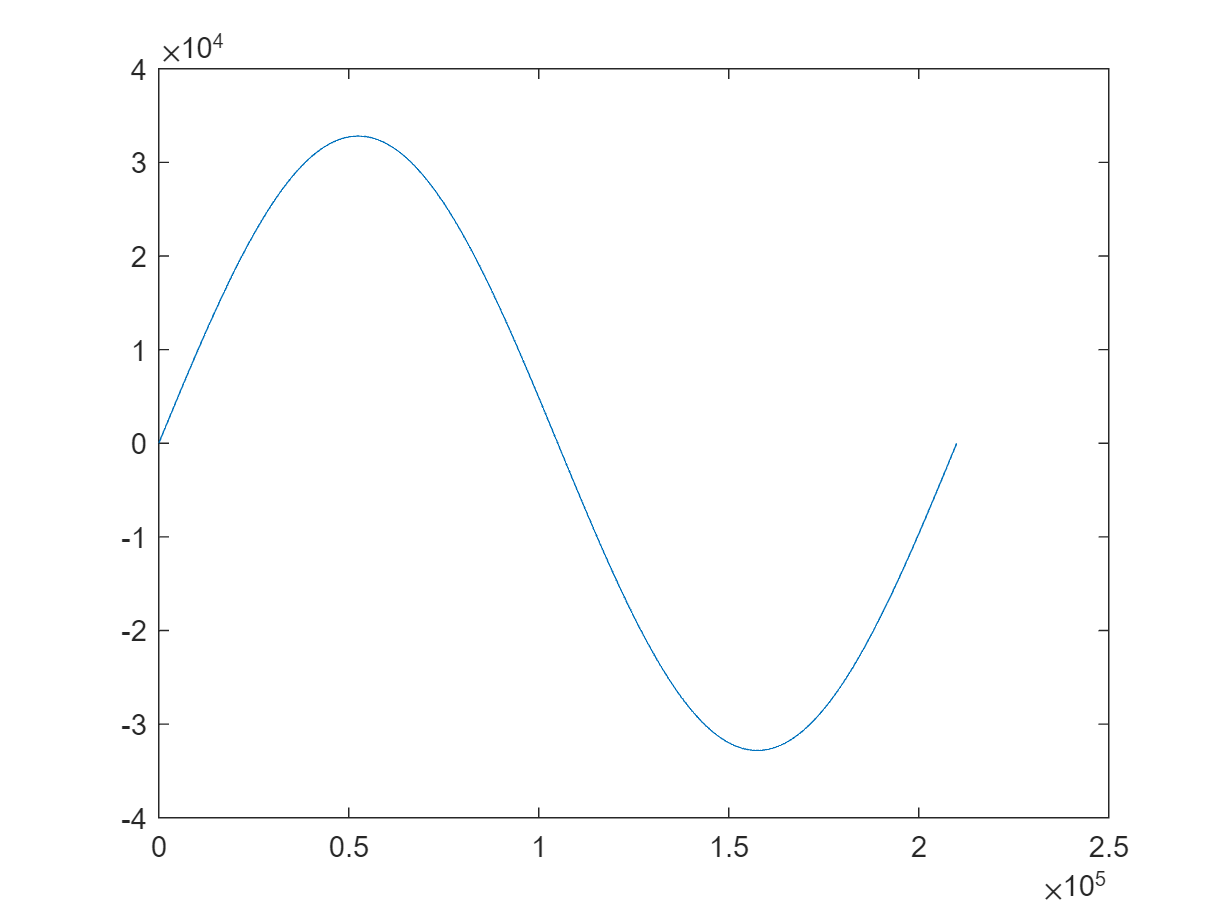


Vref = 1.8;
LSB = Vref / 2^(N-1);
MAX_CODE = 2^(N-1)-1;
MIN_CODE = -2^(N-1);

% quantization
% Negative_array = Vout_array < 0;
% quan_array = floor(Vout_array / LSB) + Negative_array;
quan_array = floor(Vout_array / LSB);
plot(quan_array(:,1));

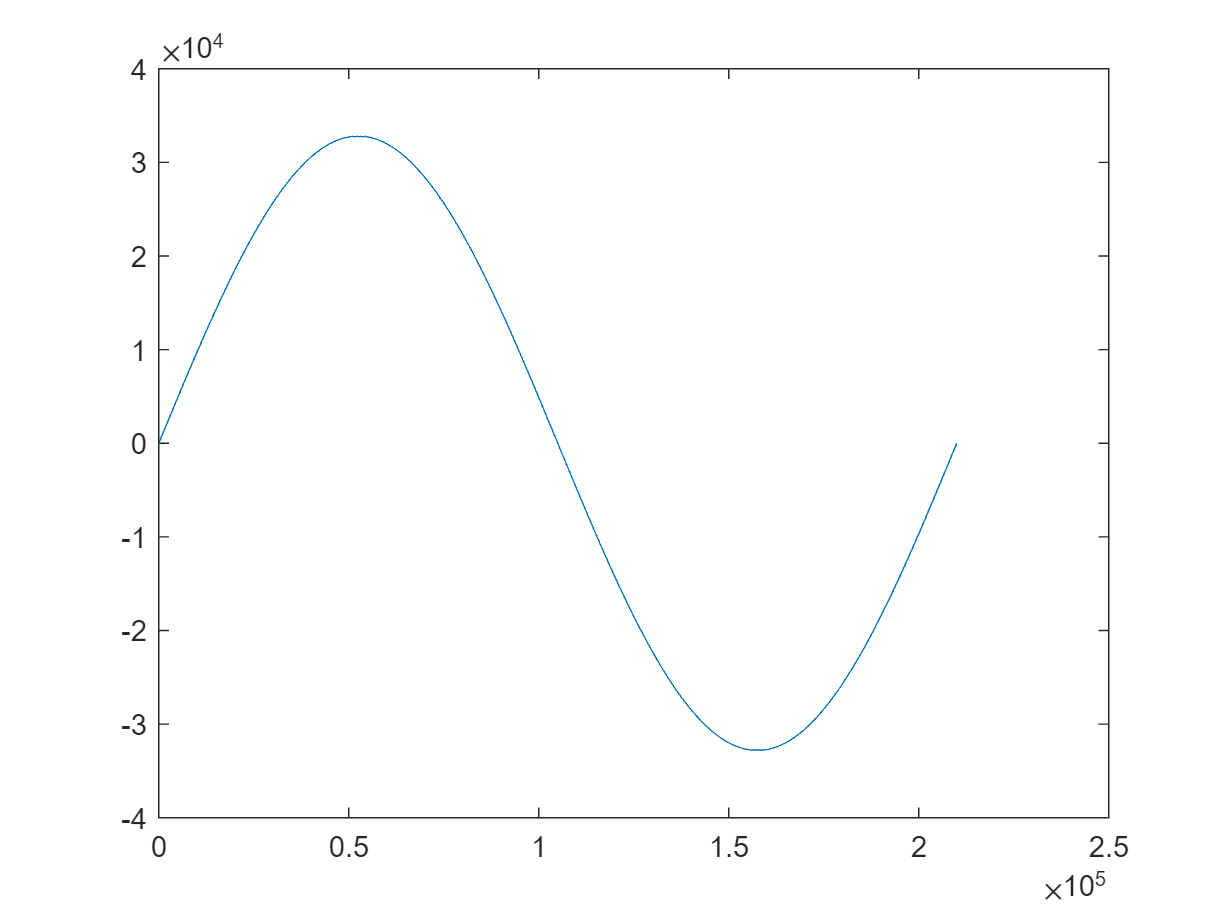


% Remove maxcode and mincode
Max_array = quan_array>=MAX_CODE; 
Min_array = quan_array<=MIN_CODE;
quan_array_fit = Max_array*MAX_CODE + Min_array*MIN_CODE + (~Max_array).*(~Min_array).*quan_array;

plot(quan_array_fit(:,1));



% quan_tb2 = tabulate(quan_array(:))
% quan_tb2 = array2table(quan_tb2, 'VariableNames',{'Code', 'Count', 'Percent'})


NUM_TOT = len_seg * num_seg;
quan_tb = tabulate(quan_array_fit(:));
quan_tb = array2table(quan_tb, 'VariableNames',{'Code', 'Count', 'Percent'})

quan_tb = 65536×3 table
     Code     Count    Percent 
    ______    _____    ________

    -32768    34170      1.6271
    -32767      400    0.019048
    -32766      400    0.019048
    -32765      380    0.018095
    -32764      380    0.018095
    -32763      380    0.018095
    -32762      380    0.018095
    -32761      380    0.018095
    -32760      360    0.017143
    -32759      360    0.017143
    -32758      360    0.017143
    -32757      360    0.017143
    -32756      360    0.017143
    -32755      340     0.01619
    -32754      360    0.017143
    -32753      340     0.01619


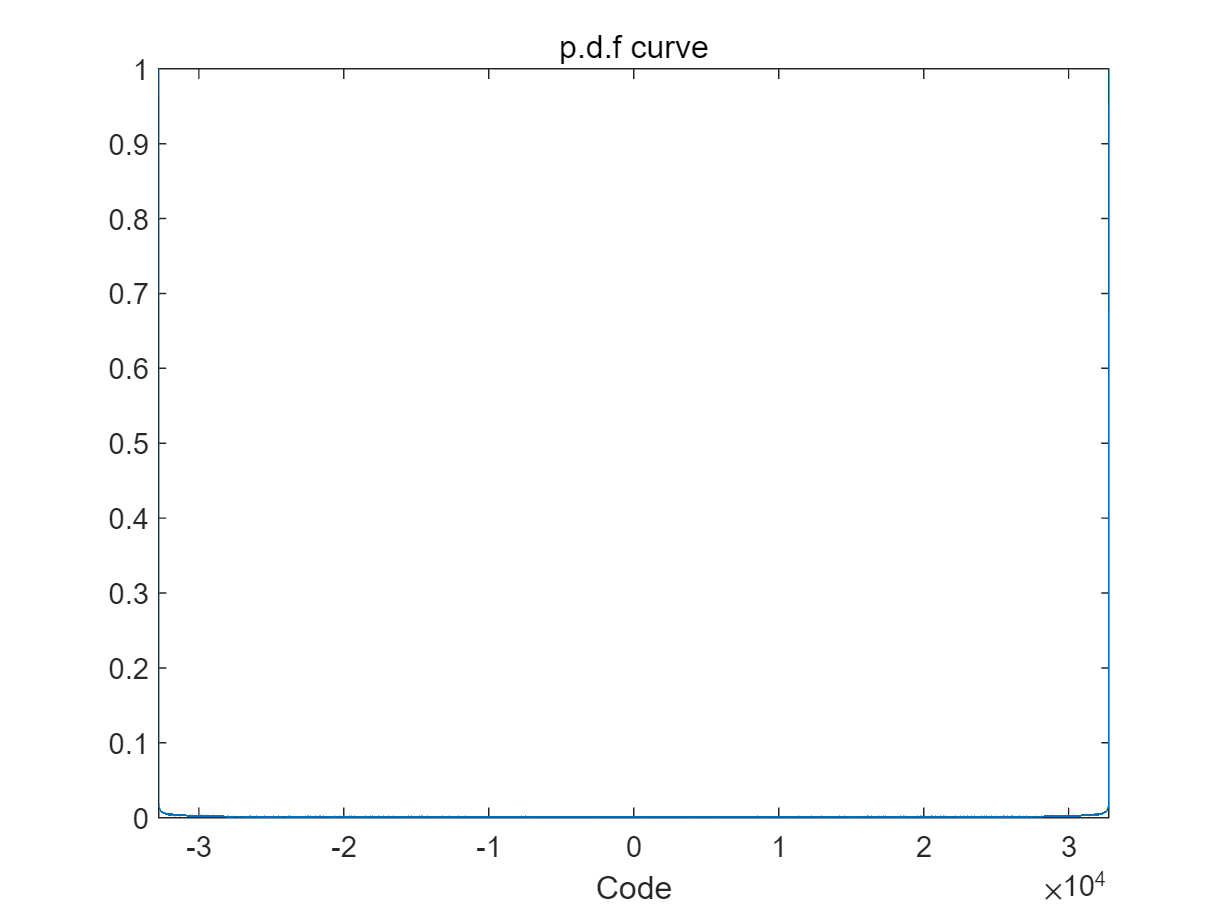

if (length(quan_tb.Code) < 2^N )
    disp(length(quan_tb.Code))
    error("数字码统计出错！")
end

% Plot pdf curve
plot(quan_tb.Code, quan_tb.Percent);
xlabel('Code');
title('p.d.f curve');
ylim([0,1]);
xlim([MIN_CODE, MAX_CODE])


% Plot cdf curve
quan_tb.Cdf = (cumsum(quan_tb.Percent)) / 100

quan_tb = 65536×4 table
     Code     Count    Percent       Cdf   
    ______    _____    ________    ________

    -32768    34170      1.6271    0.016271
    -32767      400    0.019048    0.016462
    -32766      400    0.019048    0.016652
    -32765      380    0.018095    0.016833
    -32764      380    0.018095    0.017014
    -32763      380    0.018095    0.017195
    -32762      380    0.018095    0.017376
    -32761      380    0.018095    0.017557
    -32760      360    0.017143    0.017729
    -32759      360    0.017143      0.0179
    -32758      360    0.017143    0.018071
    -32757      360    0.017143    0.018243
    -32756      360    0.017143    0.018414
    -32755      340     0.01619    0.018576
    -32754      360    0.017143    0.018748
    -32753      340     0.01619     0.01891


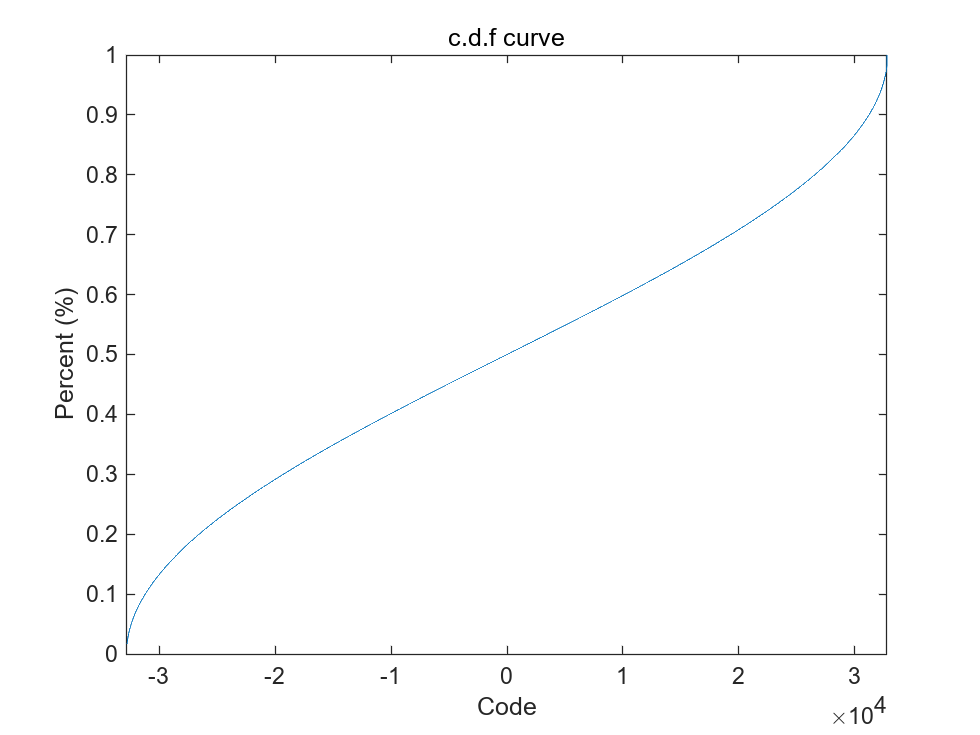

plot(quan_tb.Code, quan_tb.Cdf);
xlabel('Code');
ylabel('Percent (%)')
ylim([0,1]);
xlim([MIN_CODE, MAX_CODE])
title('c.d.f curve')


% % Curve Fit for A C
% a_list = zeros(1,num_seg);
% c_list = zeros(1,num_seg);
% 
% t = 0:1/Fs:(len_seg-1)/Fs;
% 
% myfittype = fittype('a*sin(b*t+c)+d',...
%     'dependent',{'V'},'independent',{'t'},...
%     'coefficients',{'a','b','c','d'})
% opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
% opts.StartPoint = [1.8 2*pi*33*16 0 0];
% 
% % myfit = fit(t',V1,myfittype)
% 
% for i = 1:num_seg
%     V = Vout_array(:,i);
%     myfit = fit(t',V,myfittype, opts);
%     a_list(i) = myfit.a;
%     c_list(i) = myfit.d;
% end
% 
% 
% % Display A and C
% plot(abs(a_list))
% plot(abs(c_list))

% A = (max(Vout_array(:)) - min(Vout_array(:)))/2
% A = mean(abs(a_list))
A = Vin_amp;
% C = mean(Vout_array(:))
% C = (max(Vout_array(:)) + min(Vout_array(:)))
% C = mean(abs(c_list))
C = Vin_offset;
Lm = zeros(1, 2^N-1);
for i = 1: 2^N-1
    Lm(i) = C - A*cos(pi*quan_tb.Cdf(i));
end
delta = (Lm(end) - Lm(1)) / (2^N-2)

delta = 5.4932e-05

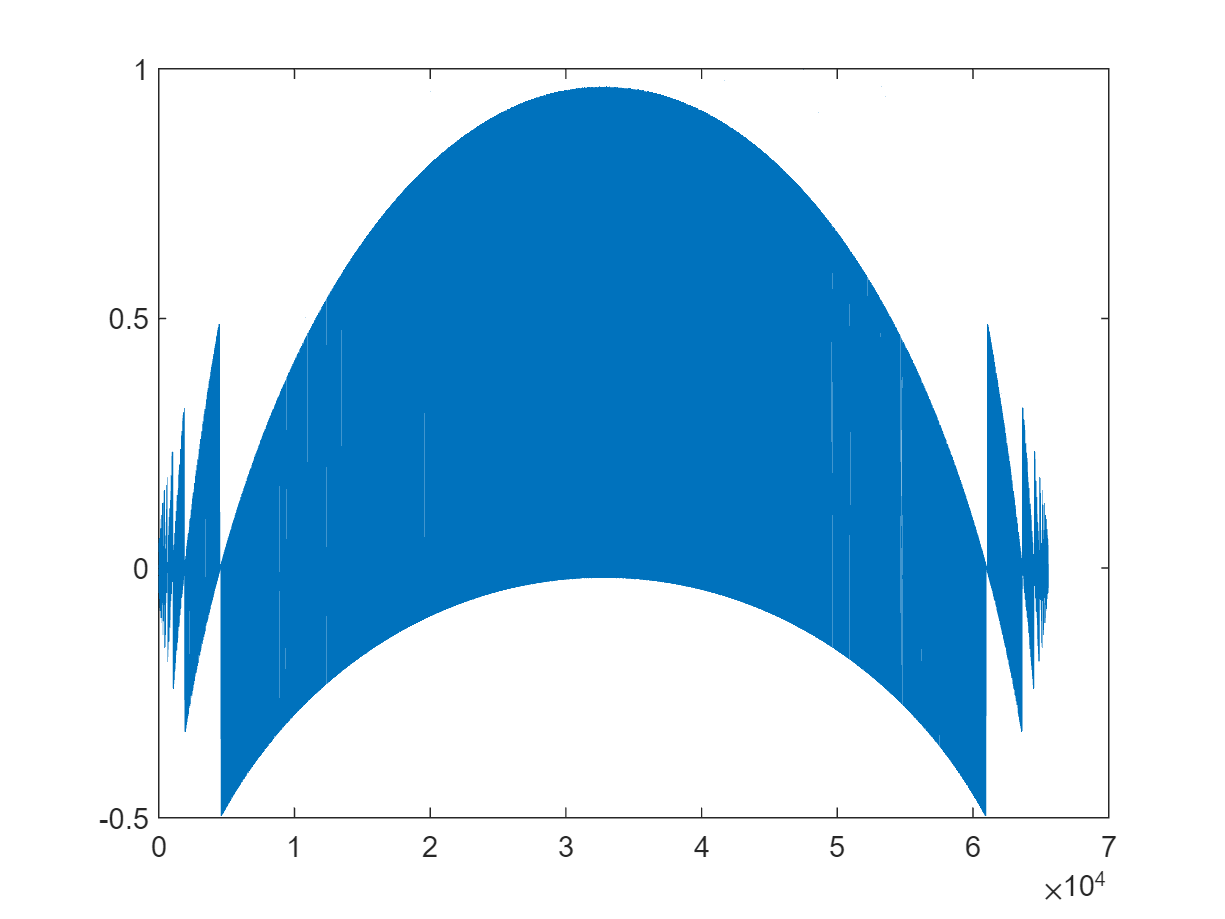


DNL = (diff(Lm) / delta) - 1;
plot(DNL)

max(abs(DNL))

ans = 0.9633

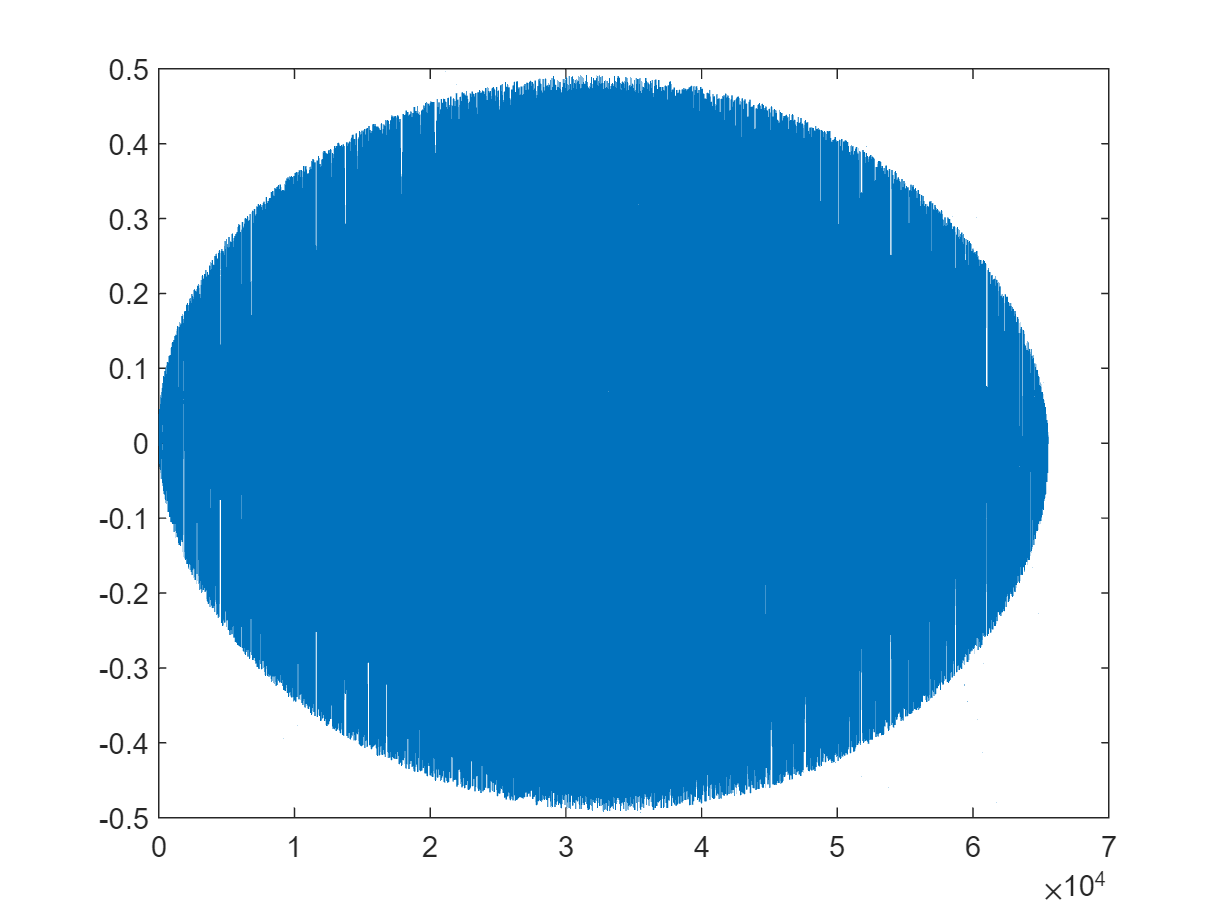

INL = cumsum(DNL);
plot(INL)

max(abs(INL))

ans = 0.4908

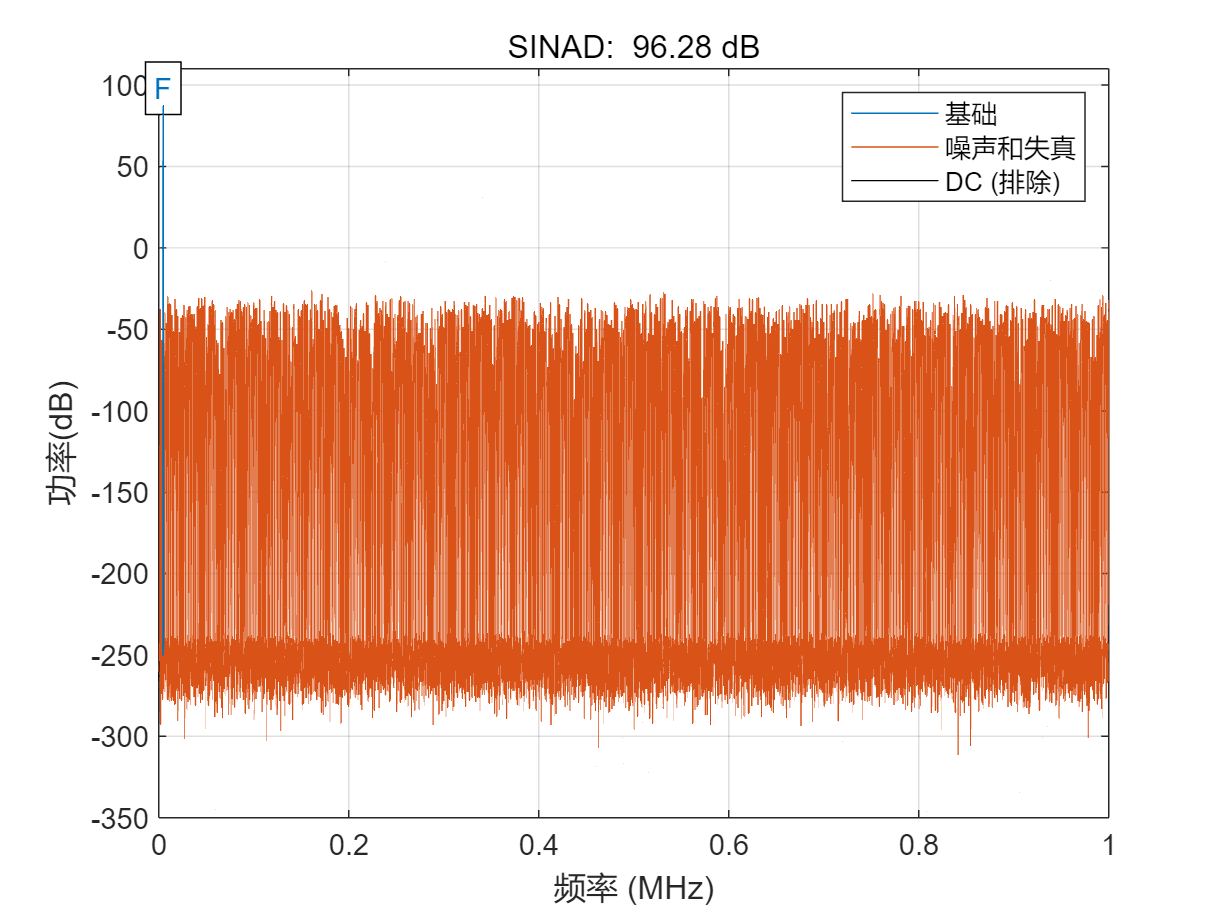


Fs = 2E6;
Fin_test = 4.6875E3;
N_Vin = 102400;
t = (0:N_Vin-1)/Fs;
Vamp = 1.795;
Vsin = Vamp*sin(2*pi*Fin_test*t);
Dout_quan = ADConversion_thres(Vsin, Lm);
Vsin_quan = ((Dout_quan/2^N)-0.5)*2*Vamp; 
% plot(t,[Vsin; Vsin_quan])
sinad(Dout_quan, Fs);

% thd(Dout_quan, Fs, 9, 'aliased')

% D1 = zeros(1, 2^N-1);
% L1 = zeros(1, 2^N-1);
% for i = 1:2^N-2
%     D1(i) = (2^N-2)*(cos(pi*quan_tb.Cdf(i))-cos(pi*quan_tb.Cdf(i+1))) / ...
%         (cos(pi*quan_tb.Cdf(1))-cos(pi*quan_tb.Cdf(2^N-1))) - 1;
%     L1(i) = (2^N-2)*(cos(pi*quan_tb.Cdf(1))-cos(pi*quan_tb.Cdf(i))) / ...
%         (cos(pi*quan_tb.Cdf(1))-cos(pi*quan_tb.Cdf(2^N-1))) - i;
% 
% end
% plot(D1)
% plot(L1)
% max(abs(L1))
% toc


function [dnl,inl] = dnl_inl_sin(y)
    %DNL_INL_SIN
    % dnl and inl ADC output
    % input y contains the ADC output
    % vector obtained from quantizing a
    % sinusoid
    % Boris Murmann, Aug 2002
    % Bernhard Boser, Sept 2002
    % histogram boundaries
    minbin=min(y);
    maxbin=max(y);
    % histogram
    h = hist(y, minbin:maxbin);
    % cumulative histogram
    ch = cumsum(h);

    % transition levels found by:
    T = -cos(pi*ch/sum(h));
    % linearized histogram
    hlin = T(2:end) - T(1:end-1);
    % truncate at least first and last
    % bin, more if input did not clip ADC
    trunc=2;
    hlin_trunc = hlin(1+trunc:end-trunc);
    % calculate lsb size and dnl
    lsb= sum(hlin_trunc) / (length(hlin_trunc));
    dnl= [0 hlin_trunc/lsb-1];
    misscodes = length(find(dnl<-0.99));
    % calculate inl
    inl= cumsum(dnl);
end

function data_N4 = ReadData(filename)
    LSB_sub = 1.8 / 2^5;
    data_origin = importdata(filename);
    data_bin = dec2bin(data_origin);
    
    % ????????
    data_sign = bin2dec(data_bin(:,1));
    data_value = bin2dec(data_bin(:,2:end));
    data_sign(data_sign==1) = -1;
    data_sign(data_sign==0) = 1; 
    
    data_value = data_value .* data_sign;
    
    % ??????????????????
    len = length(data_value) / 4;
    data_N4 = reshape(data_value, [4, len])';

    data_N4 = data_N4 * LSB_sub;
end

function Vout_calib = Calibration(data_N4, Gain)
    Vout_calib = zeros(length(data_N4), 1);
    for i = 1:length(data_N4)
        Vout_calib(i) = Calib_Gain(data_N4(i,:), Gain);
    end
end

function V_calib = Calib_Gain(V_uncalib, GainA)
    l = length(V_uncalib);
    V_calib = 0;
    for i = 1:l
        V_calib = V_calib + V_uncalib(i) / GainA^(i-1);
    end    

end
